letterds = datastore("Data\*.txt");
procletds = transform(letterds,@preprocess);
letterdata = readall(procletds)
label=categorical(extractBetween(letterds.Files,"_","_"))

target=dummyvar(label(:,2))

alphabet=['A':1:'Z' '?']

alphabet = 'ABCDEFGHIJKLMNOPQRSTUVWXYZ?'

testsample=696;
[~,y]=max(net1(letterdata(testsample,:)'));
predicted=alphabet(y)  

predicted = '?'

real=label(testsample,2)

real = categorical
     X 


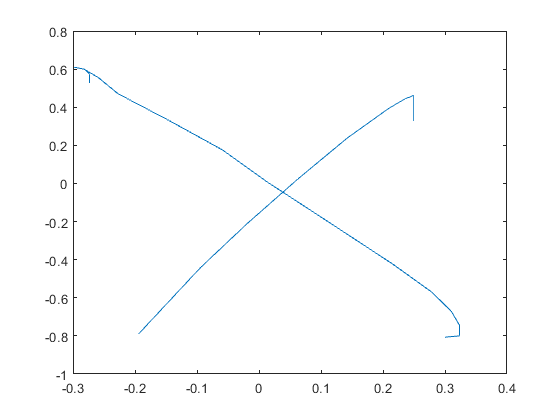

plot(letterdata(testsample,1:34),letterdata(testsample,35:68))


net1(letterdata')'

ans =     0.8146    0.0000    0.0670    0.0079    0.0029    0.0041    0.0000    0.0025    0.0015    0.0000    0.0002    0.0020    0.0002    0.0196    0.0005    0.0000    0.0311    0.0047    0.0000    0.0033    0.0009    0.0001    0.0000    0.0356    0.0000    0.0012         0
    0.0000    0.9791    0.0000    0.0000    0.0000    0.0000    0.0001    0.0014    0.0000    0.0026    0.0003    0.0000    0.0000    0.0000    0.0022    0.0006    0.0000    0.0000    0.0022    0.0000    0.0000    0.0000    0.0000    0.0000    0.0114    0.0001         0
    0.0077    0.0000    0.9255    0.0037    0.0051    0.0027    0.0038    0.0000    0.0008    0.0000    0.0000    0.0008    0.0000    0.0000    0.0006    0.0000    0.0358    0.0007    0.0014    0.0109    0.0000    0.0000    0.0000    0.0004    0.0000    0.0001         0
    0.0038    0.0000    0.0001    0.8773    0.0001    0.0010    0.0001    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0002    0.0114    0.0868    0.0000    0.0093 

target

target =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0 


dnet=traindeep(letterdata(1:end-520,:),label(1:end-520,2),...
    letterdata(end-521:end,:),label(end-521:end,2))

sn=trainShallow(letterdata,target)


function net=traindeep(x,y,vx,vy)
    x=reshape(x',1,1,68,[])
    vx=reshape(vx',1,1,68,[]);
%     testsample=1;
%     t=x(:,:,:,testsample)
%     y(testsample)
%     plot(reshape(t(1:34),1,[]),reshape(t(35:68),1,[]))
    layers = [
        imageInputLayer([1 1 68],"Name","imageinput","Normalization","none")
        fullyConnectedLayer(100,"Name","fc_1")
        reluLayer("Name","relu")
        fullyConnectedLayer(27,"Name","fc_2")
        softmaxLayer("Name","softmax")
        classificationLayer("Name","classoutput")];

    options = trainingOptions('adam', ...
    'MaxEpochs',20, ...
    'Verbose',false, ...
    'MiniBatchSize',200, ...
    'Plots','training-progress');
     
    net=trainNetwork(x,y,layers,options);
end


function data = preprocess(data)
    % Normalize time [0 1]
    data.Time = (data.Time - data.Time(1))/(data.Time(end) - data.Time(1));
    % Fix aspect ratio
    data.X = 1.5*data.X;
    % Center X & Y at (0,0)
    data.X = data.X - mean(data.X,"omitnan");
    data.Y = data.Y - mean(data.Y,"omitnan");
    % Scale to have bounding box area = 1
    scl = 1/sqrt(range(data.X)*range(data.Y));
    data.X = scl*data.X;
    data.Y = scl*data.Y;
    
    % interp to fixed scale
    newTime=0:0.03:1;
    newx=interp1(unique(data.Time,'stable')',data.X(1:size(unique(data.Time,'stable')))',(newTime));
    newy=interp1(unique(data.Time,'stable')',data.Y(1:size(unique(data.Time,'stable')))',(newTime));
    data=[newx newy];
    

end

%%

function snet=trainShallow(x,t)
    x = x';
    t = t';
    
    % Choose a Training Function
    % For a list of all training functions type: help nntrain
    % 'trainlm' is usually fastest.
    % 'trainbr' takes longer but may be better for challenging problems.
    % 'trainscg' uses less memory. Suitable in low memory situations.
    trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.
    
    % Create a Pattern Recognition Network
    net = network;
    net.trainFcn=trainFcn;

    
    % Setup Division of Data for Training, Validation, Testing
%     net.divideParam.trainRatio = 70/100;
%     net.divideParam.valRatio = 15/100;
%     net.divideParam.testRatio = 15/100;
    
    % Train the Network
    [net,tr] = train(net,x,t);
    
    % Test the Network
    y = net(x);
    e = gsubtract(t,y);
    performance = perform(net,t,y)
    tind = vec2ind(t);
    yind = vec2ind(y);
    percentErrors = sum(tind ~= yind)/numel(tind);
    
    % View the Network
    view(net)
    
    % Plots
    % Uncomment these lines to enable various plots.
    %figure, plotperform(tr)
    %figure, plottrainstate(tr)
    %figure, ploterrhist(e)
    %figure, plotconfusion(t,y)
    %figure, plotroc(t,y)
    snet=net;
end